# Matlab Moving Average of Time-series 

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Weighted Average of Neighbors

Not actually a time-series moving average. There is a vector of a parameter value, this parameter is not been estimated, we estimate all other parameters while varying this one parameter. At different values of this parameter, there is a vector of estimates. We have estimated a model along a equi-distance grid of this exogenous parameter. Now for each of the estimated parameter, calculate a "moving-average" based on averaging across estimated neighbor values of this parameter, where neighbor distance is defined by the fixed exogenous parameter. Why do this? This can be considered a "smoother" tool, but more importantly, use the moving averages as new initial parameter guesses for a new round of estimation at each of the exogenous parameter's values. For different starting seeds, use different moving windows.

First, select out all estimates:

% Load in file
srn_excel_exa = 'C:\Users\fan\M4Econ\table\_exa\excel_exa.xlsx';
tb_estimates = readtable(srn_excel_exa);
% columns to select
ar_st_colnames = tb_estimates.Properties.VariableNames;
ar_st_colnames_sel = ["mean_h_sd", ar_st_colnames(endsWith(ar_st_colnames, '_esti'))];
% Select all estimates columns and the exogenous parameter column
mt_estimates_sel = tb_estimates{:, ar_st_colnames_sel};
% sort by the first column
mt_estimates_sel = sortrows(mt_estimates_sel, 1);
disp(mt_estimates_sel(1:10,:));

    0.0500   -3.4978   -2.6181   -2.7631   -0.9659   -0.4155   -3.1664   -4.4143
    0.1000   -3.5013   -2.6949   -2.8498   -0.9718   -0.4155   -3.1579   -4.4355
    0.1500   -3.4849   -2.8976   -3.0884   -0.9737   -0.4155   -3.1566   -4.4783
    0.2000   -3.4633   -2.7626   -2.9237   -0.9746   -0.4155   -3.1552   -4.5471
    0.2500   -3.3769   -1.4130   -1.4498   -0.9752   -0.4155   -3.1545   -4.7172
    0.3000   -3.3928   -2.7294   -2.8764   -0.9737   -0.4155   -3.1544   -4.7274
    0.3500   -3.3356   -2.5737   -2.6928   -0.9711   -0.4155   -3.1550   -4.8517
    0.4000   -3.1298   -1.7669   -1.8096   -0.9509   -0.4155   -3.1538   -5.8944
    0.4500   -3.1357   -2.2754   -2.3482   -0.9509   -0.4155   -3.1537   -6.0055
    0.5000   -3.1579   -2.6960   -2.8119   -0.9513   -0.4155   -3.1553   -6.0710



% show size
disp(size(mt_estimates_sel));

    82     8



Second, calculate moving aveage with [movmean](https://www.mathworks.com/help/matlab/ref/movmean.html#bu6jxup), take the mean of up to 33 surrounding values, 66 and 99. Note that there is only 82 elements of the array. But the movmean function's window parameter will divide the window left and right.

mt_estimates_mov33 = movmean(mt_estimates_sel, 33);
mt_estimates_mov66 = movmean(mt_estimates_sel, 66);
mt_estimates_movflat = movmean(mt_estimates_sel, size(mt_estimates_sel,1)*2);

Visualize using the [ff_graph_grid](https://fanwangecon.github.io/MEconTools/MEconTools/doc/graph/htmlpdfm/fx_graph_grid.html) function from [MEconTools](https://fanwangecon.github.io/MEconTools/) moving average for one parameter, with different windows. Note that with a moving window of 82*2, the moving average becomes flat, because there are 82 elements of the underlying "time-series", so the window needs to be 82*2 for the moving average to be fully flat.

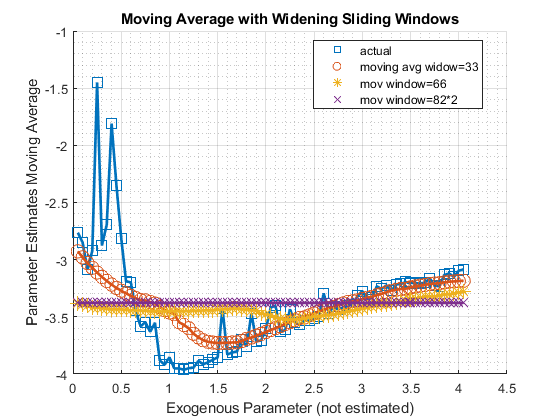

% Generate some Data
ar_row_grid = ["actual", "moving avg widow=33","mov window=66","mov window=82*2"];
ar_exo_param_grid = mt_estimates_sel(:, 1);
it_col = 4;
mt_mov_value = [mt_estimates_sel(:,it_col), ...
    mt_estimates_mov33(:,it_col), ...
    mt_estimates_mov66(:,it_col), ...
    mt_estimates_movflat(:,it_col)]'; 
% container map settings
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_graph_title') = {'Moving Average with Widening Sliding Windows'};
mp_support_graph('cl_st_ytitle') = {'Parameter Estimates Moving Average'};
mp_support_graph('cl_st_xtitle') = {'Exogenous Parameter (not estimated)'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false;
mp_support_graph('it_legend_select') = 4; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'s', 'o', '*', 'x'};
mp_support_graph('cl_colors') = 'lines';
% Call function
ff_graph_grid(mt_mov_value, ar_row_grid, ar_exo_param_grid, mp_support_graph);